# Actividad 3: Sistema de Interacción (6GDL)

- **Daniel Castillo López A01737357**

- **Emmanuel Lechuga Arreola A01736241**

- **Paola Rojas Domínguez A01737136 **

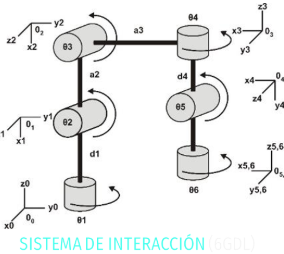

## Inicialización y Declaración de Variables

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t d1 a2 a3 d4 l5

Se configura el robot con dos articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0 0 0 0 0 0];

Creamos el vector de coordenadas generalizadas

Q= [th1, th2, th3, th4, th5, th6];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
(th1(t), th2(t), th3(t), th4(t), th5(t), th6(t))



Creamos el vector de velocidades generalizadas.

Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/  d          d          d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t), -- th6(t) |
\ dt         dt         dt         dt         dt         dt        /



Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot, en este caso 6 GDL.

GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

### Articulación 1


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$R_y \left(90\right)\left\lbrack \begin{array}{ccc}
\cos \left(90\right) & 0 & \mathrm{sen}\left(90\right)\\
0 & 1 & 0\\
-\mathrm{sen}\left(90\right) & 0 & \cos \left(90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times \left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \sin \left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$$


%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;d1];

%Matriz de rotación de la junta 1 a 2
R(:,:,1)= [0  -sin(th1)   cos(th1) ;
           0   cos(th1)   sin(th1) ;
          -1   0          0];

### Articulación 2

%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [a2*cos(th2);a2*sin(th2);0];

%Matriz de rotación de la junta 2 a 3
R(:,:,2)= [cos(th2)  -sin(th2)   0 ;
           sin(th2)   cos(th2)   0 ;
           0          0          1];

### Articulación 3 


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$R_y \left(-90\right)\left\lbrack \begin{array}{ccc}
\cos \left(-90\right) & 0 & \mathrm{sen}\left(-90\right)\\
0 & 1 & 0\\
-\mathrm{sen}\left(-90\right) & 0 & \cos \left(-90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times \left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & -\cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & -\sin \left(\theta \right)\\
1 & 0 & 0
\end{array}\right\rbrack$$



$$R_{2\ldotp 1} \left(\theta \right)\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & -\cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & -\sin \left(\theta \right)\\
1 & 0 & 0
\end{array}\right\rbrack$$



$$R_z \left(-90\right)\left\lbrack \begin{array}{ccc}
\cos \left(-90\right) & -\textrm{sen}\left(-90\right) & 0\\
\textrm{sen}\left(-90\right) & \cos \left(-90\right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
-1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & -\cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & -\sin \left(\theta \right)\\
1 & 0 & 0
\end{array}\right\rbrack \times \left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
-1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\sin \left(\theta \right) & 0 & -\cos \left(\theta \right)\\
-\cos \left(\theta \right) & 0 & -\sin \left(\theta \right)\\
0 & 1 & -1
\end{array}\right\rbrack$$


%Posición de la articulación 3 respecto a 2
P(:,:,3)= [a3*cos(th3);a3*sin(th3);0];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)=   [sin(th3)  0  -cos(th3);
            -cos(th3)  0  -sin(th3);
             0         1  -1];

### Articulación 4


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$R_x \left(-90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(-90\right) & -\sin \left(-90\right)\\
0 & \sin \left(-90\right) & \cos \left(-90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 1\\
0 & -1 & 0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 1\\
0 & -1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & -\mathrm{sen}\left(\theta \right)\\
\mathrm{sen}\left(\theta \right) & 0 & \cos \left(\theta \right)\\
0 & -1 & 0
\end{array}\right\rbrack$$


%Posición de la articulación 4 respecto a 3
P(:,:,4)= [0;0;-d4];

%Matriz de rotación de la junta 4 respecto a 3
R(:,:,4)=   [cos(th4) 0  -sin(th4);
             sin(th4) 0   cos(th4);
             0       -1   0];

### Articulación 5


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$R_x \left(90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(90\right) & -\sin \left(90\right)\\
0 & \sin \left(90\right) & \cos \left(90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & \mathrm{sen}\left(\theta \right)\\
\mathrm{sen}\left(\theta \right) & 0 & -\cos \left(\theta \right)\\
0 & 1 & 0
\end{array}\right\rbrack$$


%Posición de la articulación 5 respecto a 4
P(:,:,5)= [l5*cos(th5);l5*sin(th5);0];

%Matriz de rotación de la junta 5 respecto a 4
R(:,:,5)=   [cos(th5) 0  sin(th5);
             sin(th5) 0 -cos(th5);
             0        1  0];

### Articulación 6


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Posición de la articulación 6
P(:,:,6)= [0;0;0];

%Matriz de rotación de la junta 6
R(:,:,6)=   [cos(th6) -sin(th6)  0;
             sin(th6)  cos(th6)  0;
               0         0       1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty(A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      d1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación global T1
/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      d1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación local A2
/ cos(th2(t)), -sin(th2(t)), 0, a2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, a2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2
/ -sin(th1(t)) sin(th2(t)), -cos(th2(t)) sin(th1(t)), cos(th1(t)), -a2 sin(th1(t)) sin(th2(t)) \
|                                                                                              |
|  cos(th1(t)) sin(th2(t)),  cos(th1(t)) cos(th2(t)), sin(th1(t)),  a2 cos(th1(t)) sin(th2(t)) |
|                                                                                              |
|       -cos(th2(t)),              sin(th2(t)),            0,          d1 - cos(th2(t)) a2     |
|                                                                                              |
\             0,                        0,                 0,                   1              /



Matriz de Transformación local A3
/  sin(th3(t)), 0, -cos(th3(t)), a3 cos(th3(t)) \
|                                               |
| -cos(th3(t)), 0, -sin(th3(t)), a3 sin(th3(t)) |
|                                               |
|       0,      1,      -1,             0       |
|                                               |
\       0,      0,       0,             1       /



Matriz de Transformación global T3
/  sin(th1(t)) cos(#2), cos(th1(t)),  cos(th2(t)) sin(th1(t)) sin(th3(t)) - cos(th1(t)) + cos(th3(t)) sin(th1(t)) sin(th2(t)),           -sin(th1(t)) #1         \
|                                                                                                                                                                |
| -cos(th1(t)) cos(#2), sin(th1(t)), - sin(th1(t)) - cos(th1(t)) cos(th2(t)) sin(th3(t)) - cos(th1(t)) cos(th3(t)) sin(th2(t)),          cos(th1(t)) #1          |
|                                                                                                                                                                |
|       -sin(#2),            0,                                               cos(#2),                                          d1 - cos(#2) a3 - cos(th2(t)) a2 |
|                                                                                                                                                     

Matriz de Transformación local A4
/ cos(th4(t)),  0, -sin(th4(t)),  0  \
|                                    |
| sin(th4(t)),  0,  cos(th4(t)),  0  |
|                                    |
|      0,      -1,       0,      -d4 |
|                                    |
\      0,       0,       0,       1  /



Matriz de Transformación global T4
/ cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) cos(#4),    #1,    cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#4),             - sin(th1(t)) #3 + #1 d4            \
|                                                                                                                                                                                 |
| sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) cos(#4),    #2,    cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#4),              cos(th1(t)) #3 + #2 d4             |
|                                                                                                                                                                                 |
|                    -cos(th4(t)) sin(#4),                   -cos(#4),                    sin(th4(t)) sin(#4),                    - cos(#4) d4 + d1 - cos(#4) a3 - cos(th2(t)) a2 |
|                                                                

Matriz de Transformación local A5
/ cos(th5(t)), 0,  sin(th5(t)), l5 cos(th5(t)) \
|                                              |
| sin(th5(t)), 0, -cos(th5(t)), l5 sin(th5(t)) |
|                                              |
|      0,      1,       0,             0       |
|                                              |
\      0,      0,       0,             1       /



Matriz de Transformación global T5
/             cos(th5(t)) #4 - sin(th5(t)) #1,             cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#6),            cos(th5(t)) #1 + sin(th5(t)) #4,                                   l5 cos(th5(t)) #4 - sin(th1(t)) #5 - d4 #1 - l5 sin(th5(t)) #1                       \
|                                                                                                                                                                                                                                                                                        |
|             sin(th5(t)) #2 + cos(th5(t)) #3,             cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#6),            sin(th5(t)) #3 - cos(th5(t)) #2,                                   d4 #2 + cos(th1(t)) #5 + l5 cos(th5(t)) #3 + l5 sin(th5(t)) #2                       |
|                                                                                                                   

Matriz de Transformación local A6
/ cos(th6(t)), -sin(th6(t)), 0, 0 \
|                                 |
| sin(th6(t)),  cos(th6(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación global T6
/          sin(th6(t)) #3 - cos(th6(t)) #1,                   sin(th6(t)) #1 + cos(th6(t)) #3,                      cos(th5(t)) #7 + sin(th5(t)) #8,                                      l5 cos(th5(t)) #8 - sin(th1(t)) #6 - d4 #7 - l5 sin(th5(t)) #7                         \
|                                                                                                                                                                                                                                                                                |
|          sin(th6(t)) #4 + cos(th6(t)) #2,                   cos(th6(t)) #4 - sin(th6(t)) #2,                      sin(th5(t)) #10 - cos(th5(t)) #9,                                    d4 #9 + cos(th1(t)) #6 + l5 cos(th5(t)) #10 + l5 sin(th5(t)) #9                         |
|                                                                                                                                           

## Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Derivadas parciales de x 
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);
Jv15= functionalDerivative(PO(1,1,GDL), th5);
Jv16= functionalDerivative(PO(1,1,GDL), th6);

%Derivadas parciales de y 
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);
Jv25= functionalDerivative(PO(2,1,GDL), th5);
Jv26= functionalDerivative(PO(2,1,GDL), th6);

%Derivadas parciales de z
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);
Jv35= functionalDerivative(PO(3,1,GDL), th5);
Jv36= functionalDerivative(PO(3,1,GDL), th6);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15 Jv16;
               Jv21 Jv22 Jv23 Jv24 Jv25 Jv26;
               Jv31 Jv32 Jv33 Jv34 Jv35 Jv36]);
disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

Jacobiano lineal obtenido de forma diferencial
/ l5 cos(th1(t)) cos(th4(t)) cos(th5(t)) cos(#10) - a2 cos(th1(t)) sin(th2(t)) - l5 sin(th1(t)) sin(th5(t)) - a3 cos(th1(t)) sin(#10) - d4 cos(th1(t)) cos(th2(t)) sin(th3(t)) - d4 cos(th1(t)) cos(th3(t)) sin(th2(t)) - l5 cos(th5(t)) sin(th1(t)) sin(th4(t)) - l5 cos(th1(t)) cos(th2(t)) sin(th3(t)) sin(th5(t)) - l5 cos(th1(t)) cos(th3(t)) sin(th2(t)) sin(th5(t)) - d4 sin(th1(t)),                    -sin(th1(t)) #1,                             -sin(th1(t)) #2,           l5 cos(th5(t)) (cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#10)), l5 cos(th1(t)) cos(th5(t)) - l5 cos(th1(t)) sin(th4(t)) sin(th5(t)) - l5 cos(th2(t)) cos(th5(t)) sin(th1(t)) sin(th3(t)) - l5 cos(th3(t)) cos(th5(t)) sin(th1(t)) sin(th2(t)) - l5 cos(th4(t)) sin(th1(t)) sin(th5(t)) cos(#10), 0 \
|                                                                                                                                                                              

## Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     
     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ - d4 #21 - cos(th1(t)) #17 - #15 - #14,                    -sin(th1(t)) #11,                               -sin(th1(t)) #12,           l5 cos(th5(t)) (- cos(th2(t)) cos(th3(t)) sin(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t)) sin(th3(t)) + cos(th3(t)) cos(th4(t)) sin(th1(t)) sin(th2(t)) + sin(th1(t)) sin(th2(t)) sin(th3(t)) sin(th4(t)) + #10),                                                                                                       - (#9 + cos(th1(t)) sin(th4(t)) cos(#22)) (#19 + #18) - sin(th4(t)) sin(#22) (#15 + #14),                                                                                                      0 \
|                                                                                                                                                                                                                                                                                                        

disp('Jacobiano ángular obtenido de forma analítica'); pretty(Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0, cos(th1(t)), cos(th1(t)),            #1,           cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#4),            cos(th5(t)) #1 + sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) cos(#4))           \
|                                                                                                                                                                                                                                |
| 0, sin(th1(t)), sin(th1(t)), - sin(th1(t)) - #3 - #2, cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#4), sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) cos(#4)) - cos(th5(t)) (sin(th1(t)) + #3 + #2) |
|                                                                                                                                                                                                                                |
\ 1,      0,           0,              cos(#4)

V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/                                              l5 #12 cos(th5(t)) (- cos(th2(t)) cos(th3(t)) sin(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t)) sin(th3(t)) + cos(th3(t)) cos(th4(t)) sin(th1(t)) sin(th2(t)) + sin(th1(t)) sin(th2(t)) sin(th3(t)) sin(th4(t)) + #6) - #11 ((#5 + cos(th1(t)) sin(th4(t)) cos(#27)) (#24 + #23) + sin(th4(t)) sin(#27) (#20 + #19)) - #13 sin(th1(t)) #17 - #14 sin(th1(t)) #16 - #15 (d4 #26 + cos(th1(t)) #22 + #20 + #19)                                              \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                        

W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/ #3 (cos(th5(t)) #1 + sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) cos(#6))) + #5 #1 + #4 (cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#6)) + #8 cos(th1(t)) + #7 cos(th1(t)) \
|                                                                                                                                                                                                          |
| #4 (cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#6)) - #3 (cos(th5(t)) #2 - sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) cos(#6))) + #8 sin(th1(t)) + #7 sin(th1(t)) - #5 #2 |
|                                                                                                                                                                                                          |
|                                               _________                                                                  